## 基于数据手册损耗曲线的磁芯Core_Loss Steinmetz模型参数提取程序

针对Steinmetz模型：


$$P_\mathrm{v}=C_\mathrm{m}f^\mathrm{x}B_\mathrm{m}^\mathrm{y}$$


需要对三个参数进行提取，即Cm、x、y

**首先拿到数据手册后，得到磁芯损耗曲线，如下所示：**

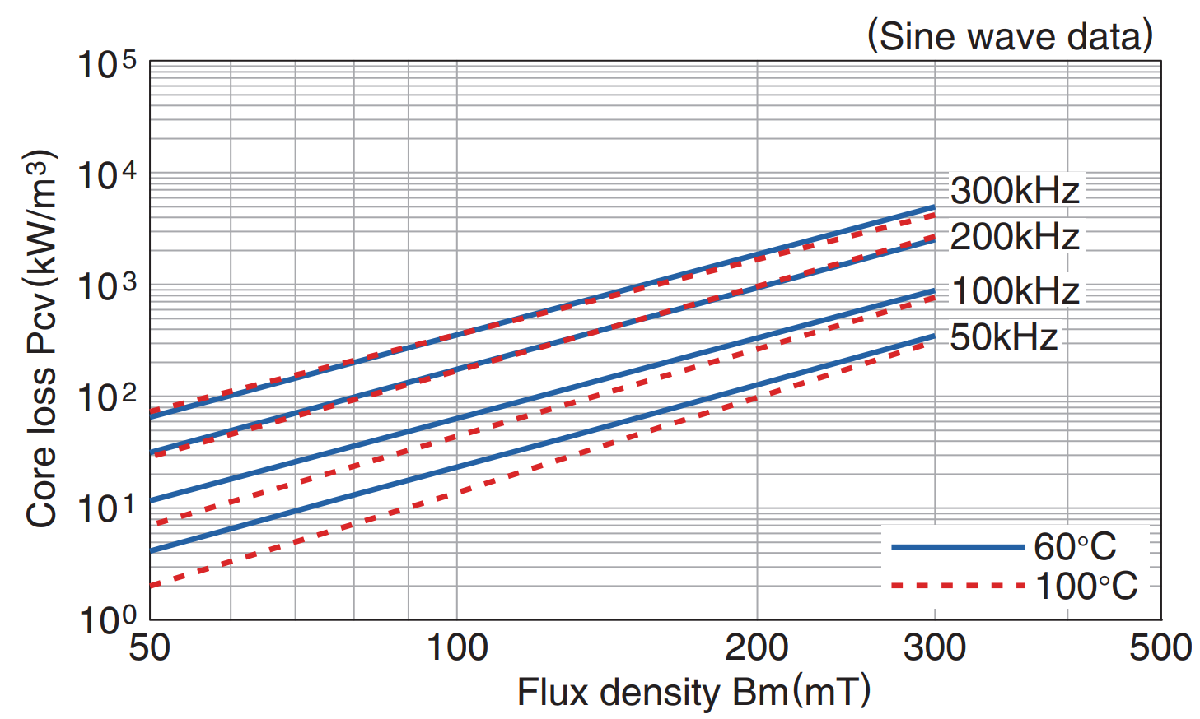

**对曲线可以使用PDF编辑器进行预先处理得到60℃下的曲线，如下所示：**

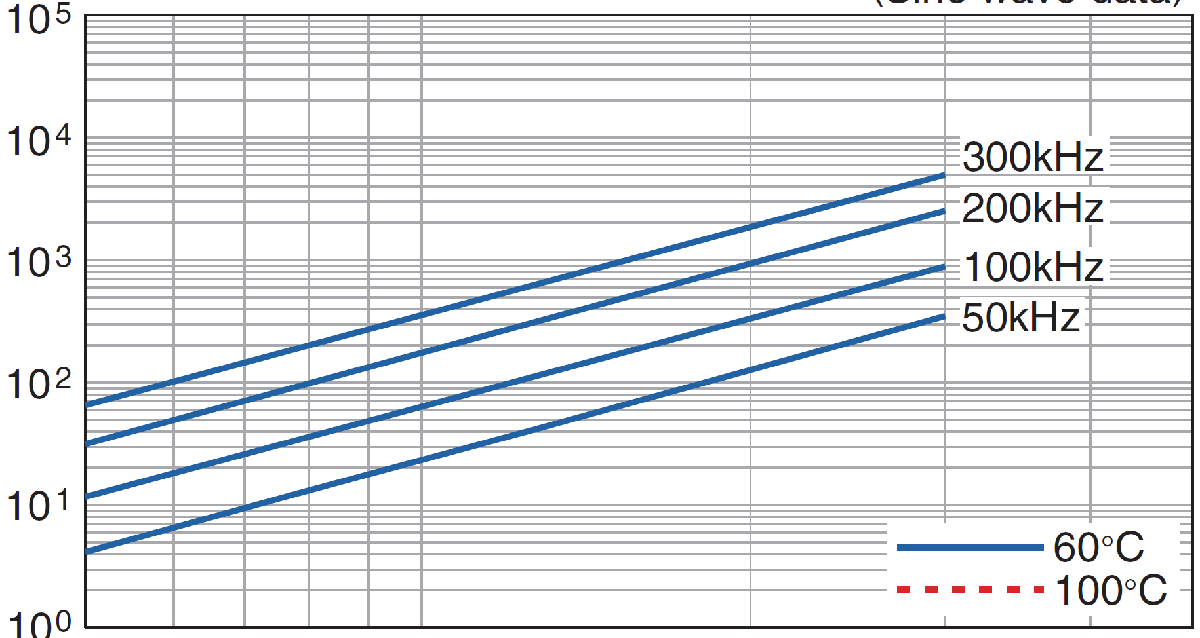

**随后使用在线曲线数据坐标提取工具对数据进行提取**[在线数据坐标提取WebPlotDigitizer](https://wpd.starrydata2.org/)

注意在网页中添加数据集时**数据集要设置为对应频率数值，单位为kHz，不要有其他非数字字符，否则后续MATLAB读取识别不到**

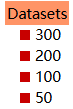

提取到的数据如下所示，共四个频率段

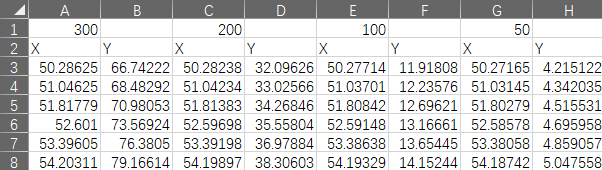

## 1.参数读取与处理

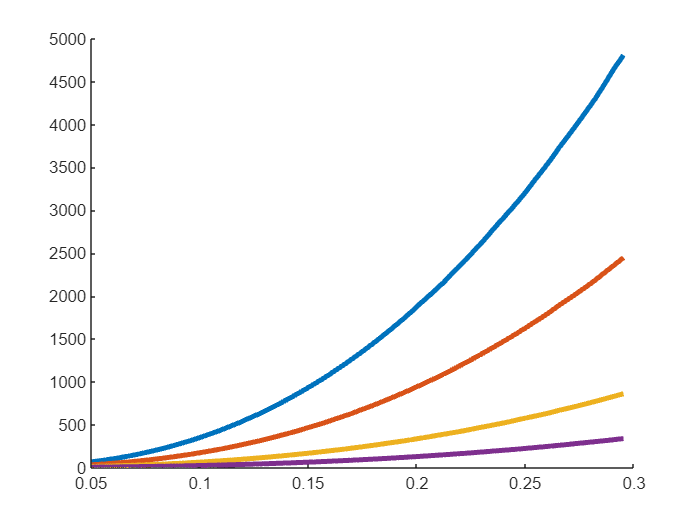

clc,clear,clf
data = readmatrix("PC95_coreloss.csv");         % 读取存有提取数据的表格
global Bm Fre Pcv n m

Bm = data(3:end-1,1)/1000;                     % 磁通密度，选择第一列作为共同的横坐标，除以1000将单位转化为mT
Fre = data(1,:)*1000;                           % 交变磁通频率，乘以1000将单位转化为Hz
Fre = Fre(~isnan(Fre));                         % 将提取到的数组中NaN值去掉
m = length(Fre);                                % 频率数组长度
n = length(Bm);                                % 磁通密度数组长度

for j = 1:m
    Pcv(:,j) = data(3:end-1,j*2);               % 磁芯损耗，n行m列的矩阵
end

figure
hold on
for j = 1:m
    plot(Bm,Pcv(:,j),'LineWidth',3)
end

## **2.设置优化初值及上下界：**

%描述公式中待定参数有10个
Para_X0=[0.0005  1.5 2.5];      % 参数初值
Para_UP=[0.00090  2   3];       % 参数上界
Para_DW=[0.0001  1   2];        % 参数下界

## 3. 编辑优化求解器：

目标为线性，约束为上、下界从方程文件f_cgd导入目标函数

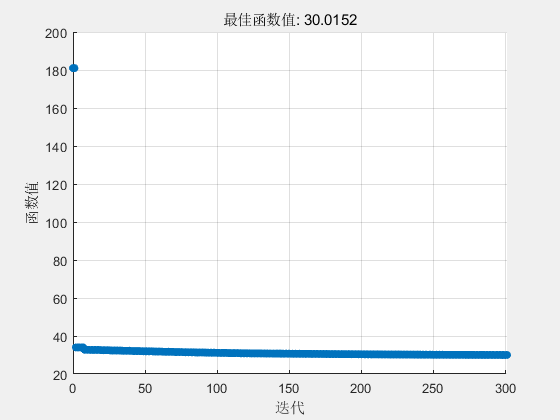

% 设置非默认求解器选项
options = optimoptions("patternsearch","Display","off","PlotFcn",...
    "psplotbestf");

% 求解
[solution,objectiveValue] = patternsearch(@f_coreloss,Para_X0,[],[],[],[],...
    Para_DW,Para_UP,[],options);


% 清除变量
clearvars options

## 4. 参数提取结果及绘图对照

solution                % 优化后的参数结果

solution =    0.000573790550232   1.500000000000000   2.449707031250000


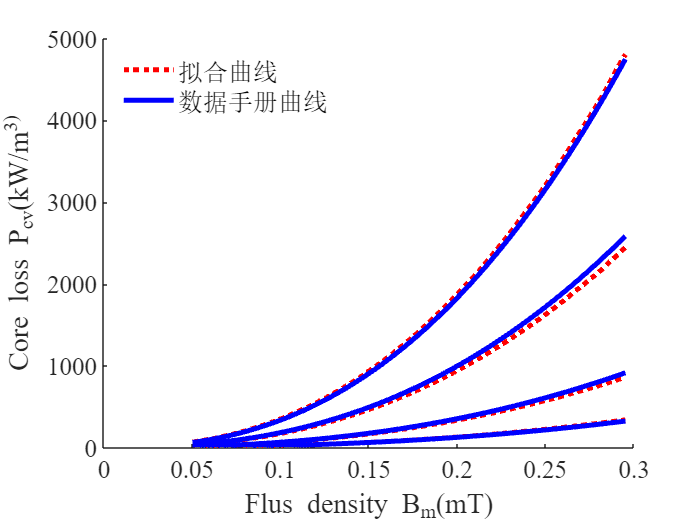

Cm = solution(1);
a = solution(2);
b = solution(3);
Pcv_cal = zeros(n,m);       % 存储根据优化后参数计算得到的功率损耗值
for j = 1:m
    for i = 1:n
        Pcv_cal(i,j) = Cm*Fre(j)^a*Bm(i)^b;
    end
end
% 绘图对比数据手册曲线和模型计算得到的曲线
figure
hold on
for j = 1:m
    plot(Bm,Pcv(:,j),'Color','r','LineWidth',3,'LineStyle',':')
    plot(Bm,Pcv_cal(:,j),'Color','b','LineWidth',3)
end

ylabel('Core loss P_{cv}(kW/m^3)','FontName','Times New Roman','FontSize',15)
xlabel('Flus density B_{m}(mT)','FontName','Times New Roman','FontSize',15)
xlim([0,0.3])
ylim([0,5000])

set(gca,'FontName','Times New Roman','FontSize',15)
h = legend('拟合曲线','','','数据手册曲线','FontName','宋体','FontSize',15,'Location','Northwest');
set(h, 'Box', 'off')